# Convolutional Neural Networks (ConvNets or CNNs)

Lily Jiang

Neurotech

Oct 2, 2023

Convolutional neural networks (convnets) were a big breakthrough in computer vision (and then have expanded beyond this). They apply a series of filters to images in the early stages of processing (somewhat like your eyes/brains do).

My individual research on convnets and my attempt to implement it is documented here.

## Intro to Neural Networks

[https://ujjwalkarn.me/2016/08/09/quick-intro-neural-networks/](https://ujjwalkarn.me/2016/08/09/quick-intro-neural-networks/)

The base unit is the neuron (aka node or unit):

- gets inputs from other nodes

- computes an output

- every input has an associated weight (w) that indicates its importance compared to other inputs

### Activation functions

The neuron applies an **activation function** (f) to the weighted sum of its inputs:

- X1 and X2 are the inputs

- w1 and w2 are the weights

- b is the bias you're introducing

**Bias**: provides every node with a trainable constant value. TODO: read more at [https://stackoverflow.com/questions/2480650/what-is-the-role-of-the-bias-in-neural-networks](https://stackoverflow.com/questions/2480650/what-is-the-role-of-the-bias-in-neural-networks) 

The activation function makes the neuron's output non-linear, which forces the neuron to be able to learn non-linear representations that actually reflect the real world.

Types of activation functions:

- sigmoid: squashes to range of [0, 1]

- tanh: squashes to range of [-1, 1]

- Rectified Linear Unit (ReLU): replaces negative values with zero

Image here: [https://ujwlkarn.files.wordpress.com/2016/08/screen-shot-2016-08-08-at-11-53-41-am.png](https://ujwlkarn.files.wordpress.com/2016/08/screen-shot-2016-08-08-at-11-53-41-am.png)

### Feedforward Neural Network

Simplest type of neural network

Has at least 2 layers of neurons (input and output), and optionally some "hidden layers"

Information only moves forward, from input to outputs

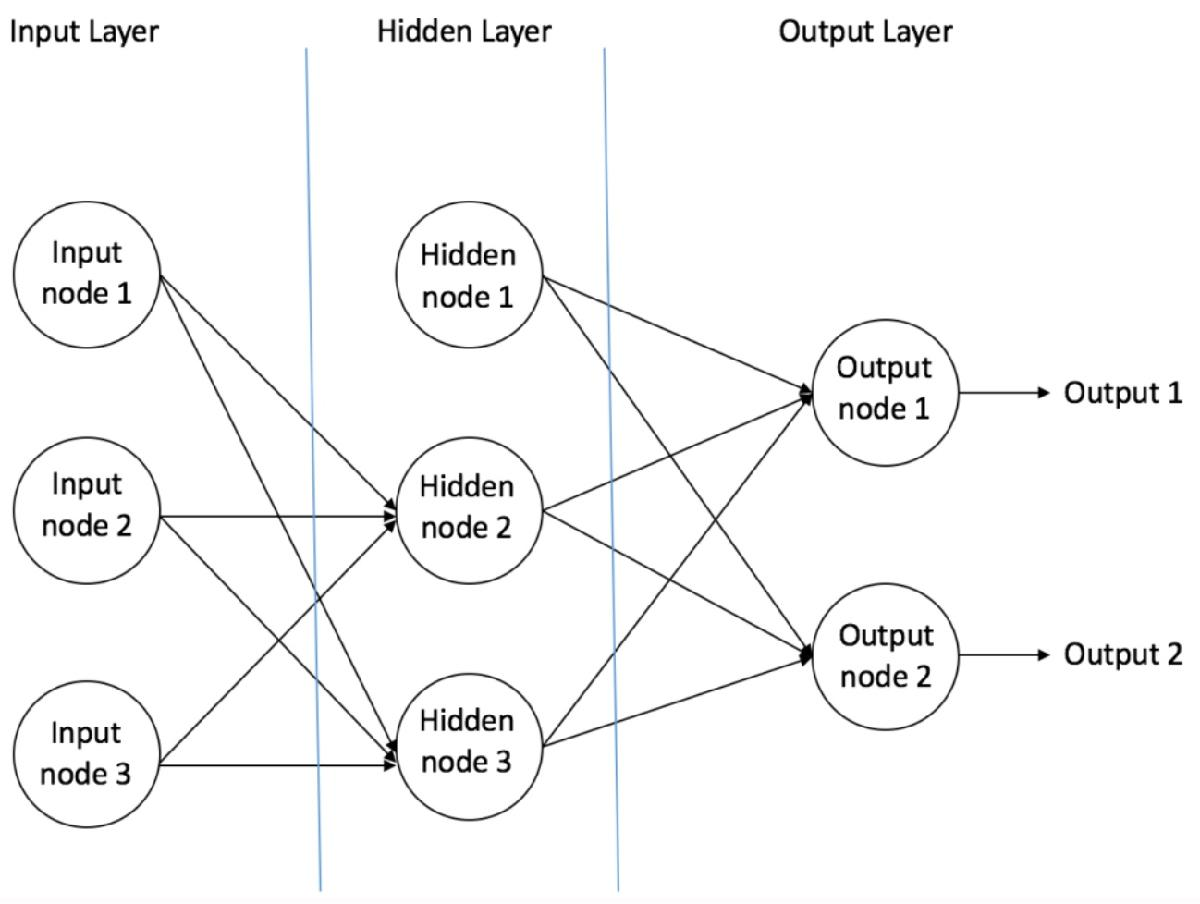

- **Input nodes**: purely for passing information to the next layer, no computation

- **Hidden nodes**: no direct connection with the outside world; used for computation. These are optional, and you can have multiple layers of them

- **Output nodes**: another round of computations, and transfers info from the network algorithm to the outside world

### **Single Layer Perceptron (SLP)**

Has no hidden layers

Can only learn linear functions

### **Multi Layer Perceptron (MLP)**

Has at least 1 hidden layer

Can learn both linear and non-linear functions

Uses **back-propagation**

With a set of features `X = (x1, x2, ...)` and a target `y`, MLP can learn classification or regression

### **Backward Propagation of Errors (BackProp)**

One of the methods to train a NN, with the **goal of assigning the best weights** for each node connection

Supervised (data is labeled)

Much like "**learning from mistakes**", where the supervisor corrects the NN when it makes one

Algorithm:

- Start by randomly assigning edge weights

- Put every training input through the NN. Compare this output to the correct output value

- If there is an error, note it and change the weights that caused it

- Repeat this process until the error falls below a predetermined threshold

- Once the threshold is met, the NN is "learned" and ready to work with new inputs

For classification, we typically use **Softmax as the Activation Function** for the output layer

- This squashes all values so they add up to 1

- This ensures the outputs are probabilities

- `Probability (Pass) + Probability (Fail) = 1`

After putting the first training data into the algorithm, the output probabilities can be calculated

- You generally want one output to be clear-cut, high probability. Ideal is one output is 1, everything else is 0

Calculate total error at output nodes, and send them back through the network to calculate gradients

- Gradient Descent adjusts all the weights in the network to reduce overall error at the output layer

## ConvNets

[https://ujjwalkarn.me/2016/08/11/intuitive-explanation-convnets/](https://ujjwalkarn.me/2016/08/11/intuitive-explanation-convnets/)

ConvNets involve 4 main operations:

- Convolution

- Non Linearity (ReLU)

- Pooling or Sub Sampling

- Classification (Fully Connected Layer)

Every image is a matrix of pixel values

Colorful images have 3 **channels** - red, green, and blue

- An image can be thought of as 3 2D matrices stacked on top of each other, one for each channel

- Each matrix has pixels in the range of 0-255 (255 = white)

Grayscale images only have 1 channel, so many algorithms are simplified by first converting to grayscale

### **Convolution**

One of the main steps in ConvNets, extracts features from the input image

- "Slide" a smaller matrix (called the **filter**, **kernel**, or **feature detector** matrix) over the image matrix you're searching through (**input image**)

- For each position, do element wise multiplication. Add the outputs to get a matrix of measurements of similarity (called the **Convolved Feature**, **Activation Map,** or **Feature Map**)

- You can actually perform operations such as Edge Detection, Sharpen and Blur by applying different filter matrices. Different filters detect different features (like curves, edges, etc)

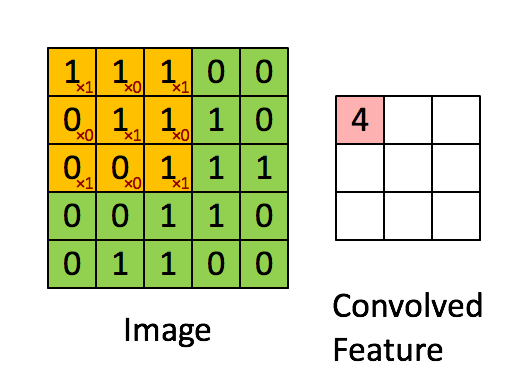

The filter matrix is derived from the training process if you add parameters like the number of filters, size, etc.

**More filters = more feature maps = more extracted features = better**

**Stride**: the number of pixels you're moving the filter matrix each time. Larger stride = smaller feature map

**Zero-padding (wide convolution)**: It can be good to "pad" the input matrix with zeros around the border. This lets you apply the filter to bordering elements, if the feature is at the very edge

- this also lets us control the size of the feature maps

- Not zero-padding is called "narrow convolution"

## ReLU (Rectified Linear Unit)

Used to introduce non-linearity into the ConvNet

Element-wise operation, so applied per pixel

Replaces all negative pixel values (which are black/dark pixels) in the feature map with 0

## Spatial Pooling

AKA Subsampling, or Downsampling

Used to reduce the number of dimensions for each feature map, while still retaining the important stuff

- smaller feature map = more managable

- reduces the number of parameters and computation, preventing overfitting

- makes the network immune to small transformations, distortions, and translations

- lets us get to an "equivariant representation", which means we can detect objects no matter where they're located in the image

Define a spatial neighborhood (like a 2x2 window), then choose a type of pooling

- **Max Pooling**: Take the largest element from the feature map. This is generally the best option

- **Average Pooling**: Take the average element

- **Sum Pooling**: Take the sum of all elements in the window

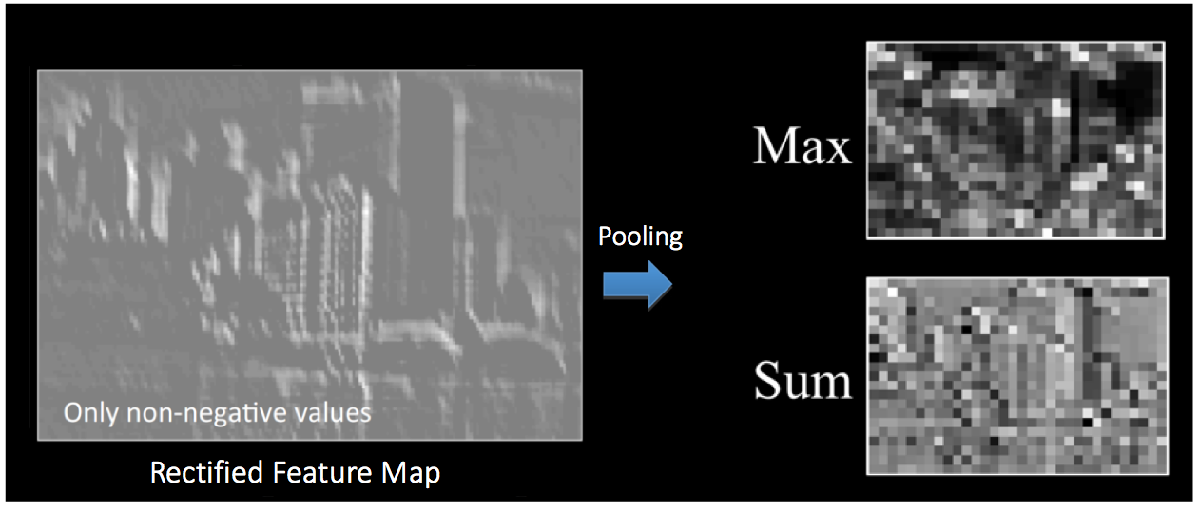

## **Combining them all (example):**

**Convolution, ReLU and Pooling are the basic building blocks of CNN**

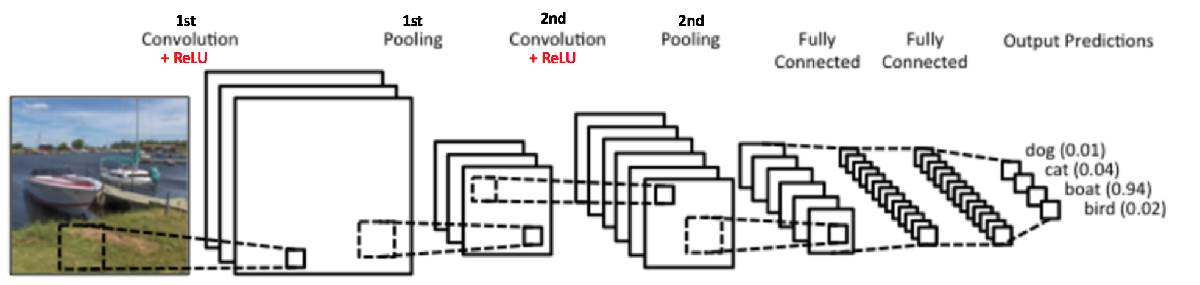

- The 2nd Convolution layer performs convolution on the output of the first Pooling Layer using six filters. This produces six feature maps

- ReLU is then applied individually to each feature map

- Max Pooling is applied individually to each rectified feature map

By combining these, we can:

- extract useful features

- introduce non-linearity

- reduce feature dimension

- attempt to make features somewhat equivariant

The output of the 2nd Pooling Layer acts as an input to the **Fully Connected Layer**.

## **Fully Connected Layer**

Multi Layer Perceptron, where **every neuron in the previous layer is connected to every neuron on the next layer**

Softmax is the activation function in the output layer

The outputs from convolutional and pooling layers show high-level features

**Purpose: classification, and also a cheap way to learn non-linear combinations of features**

## Summary

Steps to *TRAIN* the ConvNet for classification (using the network designed in the image above):

- Initialize all filters, parameters, and weights with random values

- Put a training image into the network and find the output probabilities for each class, which will be random. The image goes through forward propagation (convolution, ReLU, and pooling).

- Calculate the total error at the output layer: **Total Error = ∑ 0.5 * (target probability – output probability)²**

- Use back propagation to calculate gradients for the errors, with respect to all the weights in the network. Then **use gradient descent to change the filter matrix values and node weights** (with the goal of minimizing output error. A perfect vector is [0, 0, 1, 0], a bad vector is [0.2, 0.4, 0.1, 0.3])

- Repeat steps 2-4 for all training images

Steps for classifying a new image w/ the ConvNet:

- Go through forward propagation and calculate output probabilities for each possible class. This is done using the weights

Notes:

- You can have as many Convolution and Pooling layers as you want; the better performing ones today have tens of them

- You also don't need to have alternating Convolution and Pooling layers; it can be in any order. (question to self: is there a generally better-performing order?)

- More convolution steps = better at detecting complicated features

Other variations:

- [Convolutional Deep Belief Network](http://web.eecs.umich.edu/~honglak/icml09-ConvolutionalDeepBeliefNetworks.pdf)

- LeNet

- AlexNet

- DenseNet

[https://adamharley.com/nn_vis/](https://adamharley.com/nn_vis/)

## Train your own convnet

Dataset: [https://www.kaggle.com/datasets/preetviradiya/brian-tumor-dataset/](https://www.kaggle.com/datasets/preetviradiya/brian-tumor-dataset/)

Guide: [https://www.mathworks.com/help/deeplearning/ug/create-simple-deep-learning-network-for-classification.html](https://www.mathworks.com/help/deeplearning/ug/create-simple-deep-learning-network-for-classification.html)

The following chunk loads the dataset and specifies the labels as the folder names

clear;
datasetPath = 'Brain Tumor Data Set';
imds = imageDatastore(datasetPath,'IncludeSubfolders',true,'LabelSource','foldernames');

Let's display some of the images:

figure;
perm = randperm(4600,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Calculate the number of images in each category. We can also reference this for specifying the classes in the output layer.

labelCount = countEachLabel(imds)

labelCount = 2×2 table
       Label       Count
    ___________    _____

    Brain Tumor    2513 
    Healthy        2087 


We should also know how to get the size of each image before putting it into the network:

img = readimage(imds,1);
size(img)

ans =    512   512     3


The 3rd value in the array is 3, which indicates this has 3 color channels (likely RGB)

Now let's split the dataset into training and test subsets

numTrainFiles = 1000;  % this will be 2000 / 4600 for training
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

We can now define the layers we want in this network. Let's start super simple

layers = [
    imageInputLayer(size(img))  % [512 512 3]
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
];

Some notes about the syntax:

`convolution2dLayer`**:**

- param 1: designates filter size. Ex: if 3, filter matrix will be 3x3

- param 2: designates number of filters in this layer

- Padding, same: says to add padding to input images so every output is the same size as the input

`batchNormalizationLayer: `adds a batch normalization layer. This helps stabilize and accelerate the training of neural networks.

`reluLayer: `Adds a ReLU activation function

`maxPooling2dLayer(2,'Stride',2): `Adds a max-pooling layer

- param 1 (`2`): specifies the window for max-pooling. Ex: if 2, window will be 2x2

- `'Stride',2`: specifies the stride, which is 2 here

`fullyConnectedLayer(10):` adds a fully connected layer with 10 output neurons. This layer is typically used for the final classification step

`softmaxLayer:` applies the softmax activation function to convert the output to     a probability distribution. This will indicate which class the image likely falls under

`classificationLayer:` defines the output layer for classification tasks. It computes the classification loss and accuracy during training

We can specify the training options.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

- `'sgdm'` = stochastic gradient descent with momentum

- `'InitialLearnRate',0.01` = the gradient descent has an initial learning rate of 0.01

- `'MaxEpochs',4` = Max # of epochs (full training cycle on the entire training set). Data is shuffled between each epoch

- `'ValidationData',imdsValidation` = specify the validation data for monitoring NN accuracy

- `'ValidationFrequency',30` = specify the validation frequency for monitoring NN accuracy

- `'Plots','training-progress'` = turn the training progress plot on

The software trains the neural network on the training data and calculates the accuracy on the validation data at regular intervals during training. The validation data is not used to update the neural network weights.

We can now train the NN using training data

imdsTrainResized = imresize(imdsTrain, [300, 240]);

Error using trainNetwork
The training images are of size 512×512×3 but the input layer expects images of size 300×240×1.

net = trainNetwork(imdsTrain,layers,options);

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

- Start by randomly assigning edge weights

- Put every training input through the NN. Compare this output to the correct output value

- If there is an error, note it and change the weights that caused it

- Repeat this process until the error falls below a predetermined threshold

- Once the threshold is met, the NN is "learned" and ready to work with new inputs